clear all;

% simulation settings
DATA_CAST       = 'single';     % set to 'single' or 'gpuArray-single' to speed up computations
RUN_SIMULATION  = true;         % set to false to reload previous results instead of running simulation

pitch = 0.208/1000;
% =========================================================================
% DEFINE THE K-WAVE GRID
% =========================================================================
N_element = 64;
% set the size of the perfectly matched layer (PML)
pml_x_size = 20;            % [grid points]
pml_y_size = 10;            % [grid points]
pml_z_size = 10;            % [grid points]

% calculate the spacing between the grid points
grid_per_ele = 1;
dx = pitch/grid_per_ele;           % [m]
dy = dx;                    % [m]
dz = dx;                    % [m]

% set desired grid size in the x-direction not including the PML
x = 15/1000;                  % [m]
y = pitch*(N_element+1);
z = 0.0135;

Nx = ceil(x/dx);
Ny = ceil(y/dy);
Nz = ceil(z/dz);

% create the k-space grid
kgrid = makeGrid(Nx, dx, Ny, dy, Nz, dz);

         Update codes to use the syntax kgrid = kWaveGrid(...).



% =========================================================================
% DEFINE THE MEDIUM PARAMETERS
% =========================================================================

% define the properties of the propagation medium
c0 = 1540;                  % [m/s]
rho0 = 1000;                % [kg/m^3]
medium.alpha_coeff = 0; 	% [dB/(MHz^y cm)]
medium.alpha_power = 0;
medium.BonA = 0;

% % create the time array
% t_end = (Nx*dx)*2.2/c0;     % [s]
% kgrid.t_array = makeTime(kgrid, c0, [], t_end);

fs = 40e6;
t_end = (Nx*dx)*2.2/c0;     % [s]
kgrid.t_array = 0:1/fs:t_end;
% =========================================================================
% DEFINE THE INPUT SIGNAL
% =========================================================================

% define properties of the input signal
source_strength = 1e6;    	% [Pa]
tone_burst_freq = 1e6; 	% [Hz]
tone_burst_cycles = 3;

% create the input signal using toneBurst
input_signal = toneBurst(1/kgrid.dt, tone_burst_freq, tone_burst_cycles);

% scale the source magnitude by the source_strength divided by the
% impedance (the source is assigned to the particle velocity)
input_signal = (source_strength./(c0*rho0)).*input_signal;

% =========================================================================
% DEFINE THE ULTRASOUND TRANSDUCER
% =========================================================================

% physical properties of the transducer
transducer.number_elements = N_element;  	% total number of transducer elements
transducer.element_width = grid_per_ele;       % width of each element [grid points]
transducer.element_length = 24;  	% length of each element [grid points]
transducer.element_spacing = 0;  	% spacing (kerf  width) between the elements [grid points]
transducer.radius = inf;            % radius of curvature of the transducer [m]

% calculate the width of the transducer in grid points
transducer_width = transducer.number_elements*transducer.element_width ...
    + (transducer.number_elements - 1)*transducer.element_spacing;

% use this to position the transducer in the middle of the computational grid
transducer.position = round([1, Ny/2 - transducer_width/2, Nz/2 - transducer.element_length/2]);

% properties used to derive the beamforming delays
transducer.sound_speed = c0;                % sound speed [m/s]
transducer.focus_distance = 20e-3;          % focus distance [m]
transducer.elevation_focus_distance = 19e-3;% focus distance in the elevation plane [m]
transducer.steering_angle = 0;              % steering angle [degrees]

% apodization
transducer.transmit_apodization = 'Hanning';    

% define the transducer elements that are currently active
active_array = ones(transducer.number_elements, 1);
transducer.active_elements = active_array;

% append input signal used to drive the transducer
transducer.input_signal = input_signal;

% create the transducer using the defined settings
transducer = makeTransducer(kgrid, transducer);

         Update codes to use the syntax transducer = kWaveTransducer(...).



% print out transducer properties
transducer.properties;

 
k-Wave Transducer Properties
  transducer position:       [1   1  21]
  transducer width:          13.312mm (64 grid points)
  number of elements:        64
  number of active elements: 64 (elements 1 to 64)
  element width:             208um (1 grid points)
  element spacing (kerf):    0m (0 grid points)
  element pitch:             208um (1 grid points)
  element length:            4.992mm (24 grid points)
  sound speed:               1540m/s
  focus distance:            20mm
  elevation focus distance:  19mm
  steering angle:            0 degrees
  steering angle max:        auto degrees



%==============================================================================================
% physical properties of the transducer
receiver.number_elements = 64;  	% total number of transducer elements
receiver.element_width = grid_per_ele;       % width of each element [grid points]
receiver.element_length = 24;  	% length of each element [grid points]
receiver.element_spacing = 0;  	% spacing (kerf  width) between the elements [grid points]
receiver.radius = inf;            % radius of curvature of the transducer [m]

% calculate the width of the transducer in grid points
receiver_width = receiver.number_elements*receiver.element_width ...
    + (receiver.number_elements - 1)*receiver.element_spacing;

% use this to position the transducer in the middle of the computational grid
receiver.position = round([1, Ny/2 - receiver_width/2, Nz/2 - receiver.element_length/2]);

% properties used to derive the beamforming delays
receiver.sound_speed = c0;                % sound speed [m/s]
receiver.focus_distance = 20e-3;          % focus distance [m]
receiver.elevation_focus_distance = 19e-3;% focus distance in the elevation plane [m]
receiver.steering_angle = 0;              % steering angle [degrees]

% define the transducer elements that are currently active
number_active_elements = receiver.number_elements;
active_array = zeros(receiver.number_elements, 1);
active_array(1:number_active_elements) = 1;
receiver.active_elements = active_array;

% create the transducer using the defined settings
receiver = makeTransducer(kgrid, receiver);

         Update codes to use the syntax transducer = kWaveTransducer(...).



% print out transducer properties
receiver.properties;

 
k-Wave Transducer Properties
  transducer position:       [1   1  21]
  transducer width:          13.312mm (64 grid points)
  number of elements:        64
  number of active elements: 64 (elements 1 to 64)
  element width:             208um (1 grid points)
  element spacing (kerf):    0m (0 grid points)
  element pitch:             208um (1 grid points)
  element length:            4.992mm (24 grid points)
  sound speed:               1540m/s
  focus distance:            20mm
  elevation focus distance:  19mm
  steering angle:            0 degrees
  steering angle max:        auto degrees



% =========================================================================
% DEFINE THE MEDIUM PROPERTIES
% =========================================================================

% define a large image size to move across
Nx_tot = Nx;
Ny_tot = Ny;
Nz_tot = Nz;

% define a random distribution of scatterers for the medium
background_map_mean = 1;
background_map_std = 0.0;
background_map = background_map_mean + background_map_std*randn([Nx_tot, Ny_tot, Nz_tot]);

% define properties
sound_speed_map = c0*ones(Nx_tot, Ny_tot, Nz_tot).*background_map;
density_map = rho0*ones(Nx_tot, Ny_tot, Nz_tot).*background_map;

simstart =  0.005;
phantom_positions = [0 0 simstart];
%     0 0 simstart+0.01];
N_scatter = size(phantom_positions,1);
for i = 1:N_scatter
    current_pos = phantom_positions(i,3);
    x_pos = round(current_pos/dx);
    density_map(x_pos, round(Ny/2), round(Nz/2)) =  density_map(x_pos, round(Ny/2), round(Nz/2)) *10;
end

medium.sound_speed = sound_speed_map;
medium.density = density_map;

% =========================================================================
% RUN THE SIMULATION
% =========================================================================

% set the input settings
input_args = {...
    'PMLInside', false, 'PMLSize', [pml_x_size, pml_y_size, pml_z_size], ...
    'DataCast', DATA_CAST, 'DataRecast', true, 'PlotSim', false};

sensor_data = kspaceFirstOrder3D(kgrid, medium, transducer, receiver, input_args{:});

Running k-Wave simulation...
  start time: 29-Aug-2023 15:59:23
  reference sound speed: 1540m/s
  prepending transducer.input_signal with 31 leading zeros
  appending transducer.input_signal with 31 trailing zeros
  dt: 25ns, t_end: 21.675us, time steps: 868
  input grid size: 73 by 65 by 65 grid points (15.184 by 13.52 by 13.52mm)
  maximum supported frequency: 3.6512MHz by 3.645MHz by 3.645MHz
  expanding computational grid...
  computational grid size: 113 by 85 by 85 grid points
           Use dimension sizes with lower prime factors to improve speed
  casting variables to single type...
  precomputation completed in 0.42434s
  starting time loop...
  estimated simulation time 1min 32.9802s...
  simulation completed in 1min 41.7016s
  recasting variables to double...
  total computation time 1min 42.14s


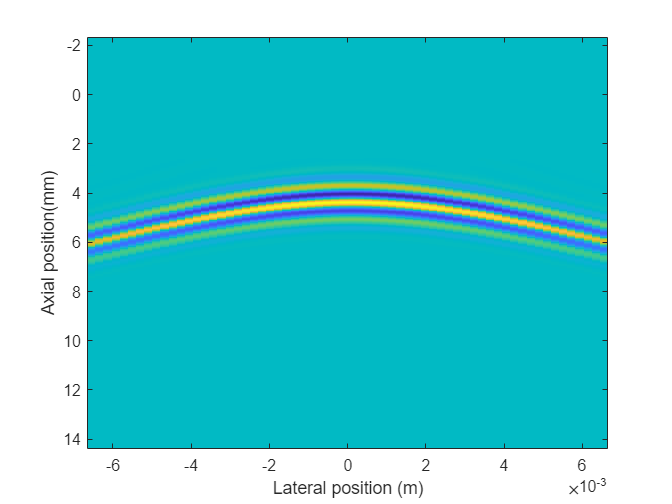


scan_line_win = getWin(kgrid.Nt*2, 'Tukey', 'Param', 0.05).';
scan_line_win = [zeros(1, length(input_signal)*2), scan_line_win(1:end/2 - length(input_signal)*2)];
scan_lines_k = bsxfun(@times, scan_line_win, sensor_data);
scan_lines_fund = gaussianFilter(scan_lines_k, 1/kgrid.dt, tone_burst_freq, 100, true);
if mod(N_element,2)==0
    extreme = (N_element/2-1/2)*pitch;
else
    extreme = (N_element-1)/2*pitch;
end

aperture_center_array = linspace(-extreme, extreme, N_element)';

t0 = length(input_signal)*kgrid.dt/2;
r = c0*( (1:length(kgrid.t_array))*kgrid.dt/2 - t0);
close all;
imagesc(aperture_center_array,r*1000,scan_lines_fund');
xlabel('Lateral position (m)');
ylabel('Axial position(mm)');